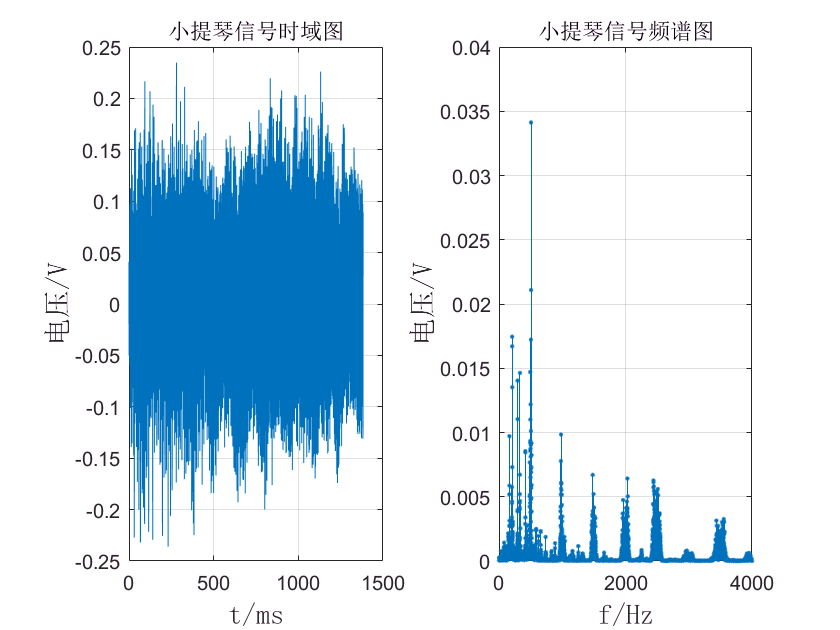

clear;
clc;
format long;
close all;

% ==========原始信号========== %
[x, fs] = audioread('./Audio/实验四语音信号/小提琴.wav');
x = x(:, 1);
x = x';

N = length(x);  % 整个图由N1个样点构成
dt = 1 / fs;
tscale = dt * N;  % X轴显示的时间长度，单位为秒
t = 0 : dt : tscale - tscale / N;

subplot(1, 2, 1);
% subplot(2, 4, 1);
plot(t .* 1000, x);
title('小提琴信号时域图');
xlabel('t/ms', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
ylabel('电压/V', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
grid on;

y = fft(x);
realy = 2 * abs(y(1 : length(x))) / length(x);
realf = (0 : length(x) - 1) * (fs / length(x)); 
subplot(1, 2, 2);
% subplot(2, 4, 5);
stem(realf, realy, '.');
title('小提琴信号频谱图');
axis([0, 4000, 0, 0.04]);
xlabel('f/Hz', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
ylabel('电压/V', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
grid on;

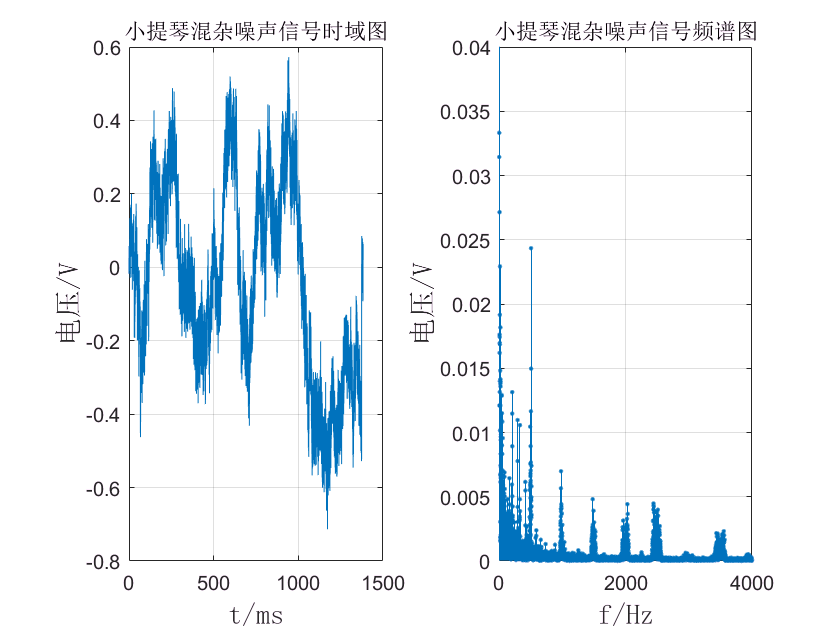


figure;
% ==========小提琴混杂噪声信号========== %
[Xn, fs1] = audioread('./Audio/实验四语音信号/小提琴混杂声音_缩混.wav');
Xn = Xn(:, 1);
Xn = Xn';

N1 = length(Xn);  % 整个图由N1个样点构成
dt1 = 1 / fs1;
tscale1 = dt1 * N1;  % X轴显示的时间长度，单位为秒
t1 = 0 : dt1 : tscale1 - tscale1 / N1;

subplot(1, 2, 1);
% subplot(2, 4, 2);
plot(t1 .* 1000, Xn);
title('小提琴混杂噪声信号时域图');
xlabel('t/ms', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
ylabel('电压/V', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
grid on;

Y1 = fft(Xn);
realy = 2 * abs(Y1(1 : length(Xn))) / length(Xn);
realf = (0 : length(Xn) - 1) * (fs1 / length(Xn)); 
subplot(1, 2, 2);
% subplot(2, 4, 6);
stem(realf, realy, '.');
title('小提琴混杂噪声信号频谱图');
axis([0, 4000, 0, 0.04]);
xlabel('f/Hz', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
ylabel('电压/V', 'FontName', '宋体', 'FontWeight', 'normal', 'FontSize', 14);
grid on;